% 2011 Placebo-predictive maps
[PlaceboPvsC_Antic, names] = load_image_set('PlaceboPvsC_Antic');

Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Loaded images:
/Users/f003vz1/Documents/GitHub/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2011_Wager_JNeuro_placebo_prediction/Multivariate_PlaceboPredict_Anticipation/PlaceboPredict_Anticipation.img


[PlaceboPvsC_Pain, names] = load_image_set('PlaceboPvsC_Pain');

Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Loaded images:
/Users/f003vz1/Documents/GitHub/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2011_Wager_JNeuro_placebo_prediction/Multivariate_PlaceboPredict_PainPeriod/PlaceboPredict_PainPeriod.img



% 2021 Spisak Placebo meta N = 603 maps
fname = which('full_pain_g_pperm_FWE05.nii.gz');
pain603 = fmri_data(fname);

Using default mask: /Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
Elapsed time is 0.995086 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 21975  Bit rate: 14.42 bits



fname = which('full_pla_g_pperm_tfce_FWE05.nii.gz');
placebo603 = fmri_data(fname);

Using default mask: /Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
Elapsed time is 0.743733 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6243  Bit rate: 12.61 bits



fname = which('full_pla_rrating_pperm_tfce_FWE05.nii.gz');
placebocorr603 = fmri_data(fname);

Using default mask: /Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
Elapsed time is 1.116994 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 10905  Bit rate: 13.41 bits


% NOTE: For flat maps, work in progress - see
% canlab_cat12_map_nii_to_surface.m

% https://github.com/ThomasYeoLab/CBIG/tree/master/stable_projects/registration/Wu2017_RegistrationFusion
%
%
% https://www.diedrichsenlab.org/imaging/propatlas.htm
% https://journals.plos.org/plosone/article?id=10.1371/journal.pone.0133402
%
% https://github.com/diedrichsenlab/cerebellar_atlases
%
% "Multi-domain task battery (MDTB) parcellation and contrasts: King et al. (2019)"
% "Diedrichsen, J." 47 tasks
% https://github.com/DiedrichsenLab/cerebellar_atlases/tree/master/King_2019

% See
% render_on_cerebellar_flatmap.m



### Plot montages of placebo-related effects

create_figure('montage'); axis off; h = montage(PlaceboPvsC_Antic);
h.title_montage(5, 'Placebo-predictive, Anticipation (2011)');

create_figure('montage'); axis off; h = montage(PlaceboPvsC_Pain);
h.title_montage(5, 'Placebo-predictive, During Pain (2011)');


### Prep and show cerebellar montage


create_figure('wedge'); 
h = wedge_plot_by_atlas(PlaceboPvsC_Antic, 'atlases', {'cerebellum'}, 'montage');

----------------------------------------------
Placebo-predictive, Anticipation (2011)
----------------------------------------------
Setting up fmridisplay objects
sagittal montage: 4501 voxels displayed, 300533 not displayed on these slices
sagittal montage: 4470 voxels displayed, 300564 not displayed on these slices
sagittal montage: 4461 voxels displayed, 300573 not displayed on these slices
axial montage: 32192 voxels displayed, 272842 not displayed on these slices
axial montage: 34779 voxels displayed, 270255 not displayed on these slices
Prepping atlases: 
cerebellum Loading atlas: /Users/f003vz1/Documents/GitHub/MasksPrivate/Masks_private/2009_Diedrichsen_SUIT_Cerebellum-MNIsegment-MRICroN/SUIT_Cerebellum_MNI_atlas_object.mat
Note: Mean weights reflect homogeneity in sign and magnitude across region,
not high spatial frequency/pattern information.


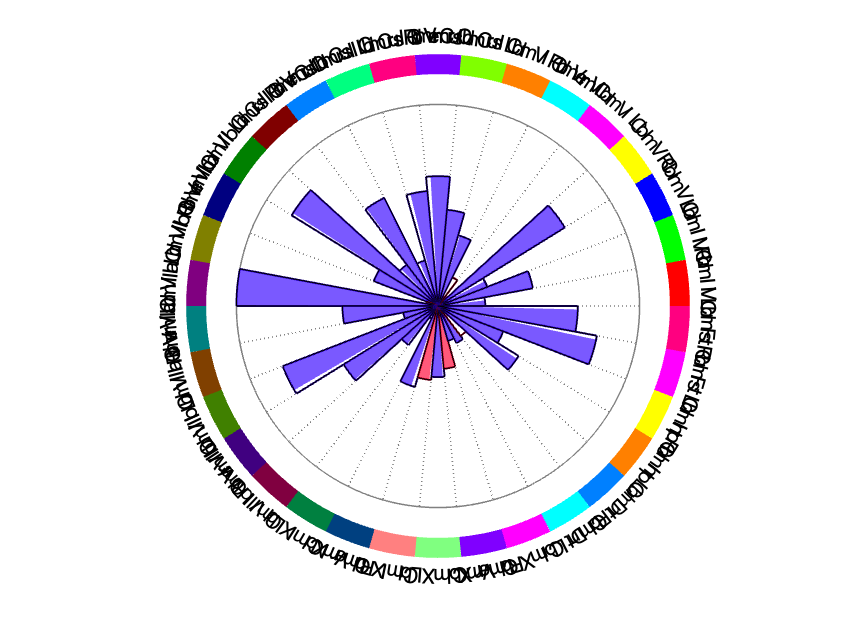

____________________________________________________________________________________________________________________________________________
Wedge plot:
Wedge plots depict mean images values across voxels. Red indicates positive values and blue negative values. If multiple images were 
entered, the darker shaded area indicates the standard error of the mean (SEM) across individuals.                                   
____________________________________________________________________________________________________________________________________________
           Label               Value   
    ____________________    ___________

    {'Cblm I IV L'     }    -2.1155e-06
    {'Cblm I IV R'     }    -4.3187e-06
    {'Cblm V L'        }    -2.3648e-06
    {'Cblm V R'        }    -6.6804e-06
    {'Cblm VI L'       }    -3.2853e-07
    {'Cblm Verm VI'    }     1.4366e-06
    {'Cblm VI R'       }    -3.2912e-06
    {'Cbl

% Placebo predictive: Anticipation

map_obj = PlaceboPvsC_Antic;
map_name = 'Placebo-predictive, Anticipation (2011)';
t = show_cerebellar_map(map_obj, map_name);


combined_table = t;
t.Properties.RowNames{2} = 'Antic';

----------------------------------------------
Placebo-predictive, During Pain (2011)
----------------------------------------------
Setting up fmridisplay objects
sagittal montage: 1046 voxels displayed, 43813 not displayed on these slices
sagittal montage: 1276 voxels displayed, 43583 not displayed on these slices
sagittal montage: 1192 voxels displayed, 43667 not displayed on these slices
axial montage: 5523 voxels displayed, 39336 not displayed on these slices
axial montage: 5623 voxels displayed, 39236 not displayed on these slices


Prepping atlases: 
cerebellum Loading atlas: /Users/f003vz1/Documents/GitHub/MasksPrivate/Masks_private/2009_Diedrichsen_SUIT_Cerebellum-MNIsegment-MRICroN/SUIT_Cerebellum_MNI_atlas_object.mat
Note: Mean weights reflect homogeneity in sign and magnitude across region,
not high spatial frequency/pattern information.


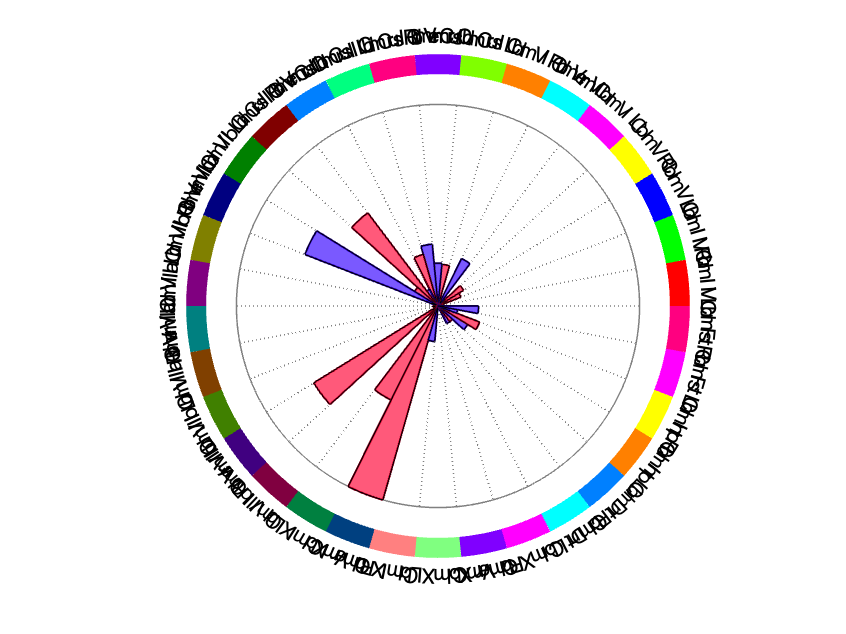

____________________________________________________________________________________________________________________________________________
Wedge plot:
Wedge plots depict mean images values across voxels. Red indicates positive values and blue negative values. If multiple images were 
entered, the darker shaded area indicates the standard error of the mean (SEM) across individuals.                                   
____________________________________________________________________________________________________________________________________________
           Label               Value   
    ____________________    ___________

    {'Cblm I IV L'     }      3.597e-06
    {'Cblm I IV R'     }     8.8511e-07
    {'Cblm V L'        }     1.4241e-05
    {'Cblm V R'        }     1.7417e-05
    {'Cblm VI L'       }     5.7451e-06
    {'Cblm Verm VI'    }    -3.0736e-05
    {'Cblm VI R'       }     2.0115e-06
    {'Cbl

% Placebo predictive: Pain 
map_obj = PlaceboPvsC_Pain;
map_name = 'Placebo-predictive, During Pain (2011)';
t = show_cerebellar_map(map_obj, map_name);


% Placebo main effect: Zunhammer meta
map_obj = placebo603;
map_name = 'Placebo main effect, Zunhammer n = 603 (2021)';
t = show_cerebellar_map(map_obj, map_name);



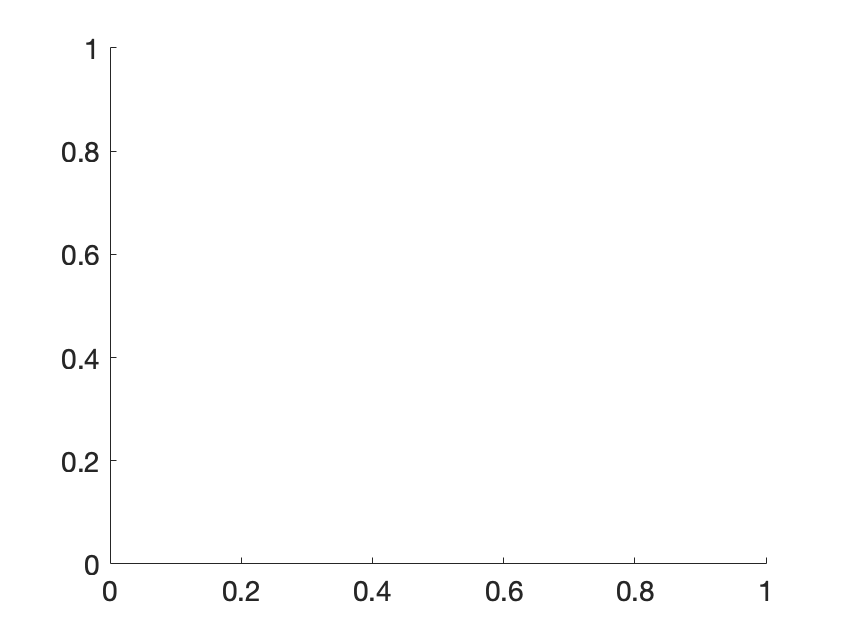




create_figure('wedge2'); 

Prepping atlases: 
cerebellum Loading atlas: /Users/f003vz1/Documents/GitHub/MasksPrivate/Masks_private/2009_Diedrichsen_SUIT_Cerebellum-MNIsegment-MRICroN/SUIT_Cerebellum_MNI_atlas_object.mat
Note: Mean weights reflect homogeneity in sign and magnitude across region,
not high spatial frequency/pattern information.


____________________________________________________________________________________________________________________________________________
Wedge plot:
Wedge plots depict mean images values across voxels. Red indicates positive values and blue negative values. If multiple images were 
entered, the darker shaded area indicates the standard error of the mean (SEM) across individuals.                                   
____________________________________________________________________________________________________________________________________________


[hh, output_values_by_region, labels, atlas_obj, colorband_colors] = wedge_plot_by_atlas(PlaceboPvsC_Pain, 'atlases', {'cerebellum'});


t = table(labels{1}', output_values_by_region{1}', 'VariableNames', {'Label' 'Value'})

t = 34×2 table
           Label               Value   
    ____________________    ___________

    {'Cblm I IV L'     }      3.597e-06
    {'Cblm I IV R'     }     8.8511e-07
    {'Cblm V L'        }     1.4241e-05
    {'Cblm V R'        }     1.7417e-05
    {'Cblm VI L'       }     5.7451e-06
    {'Cblm Verm VI'    }    -3.0736e-05
    {'Cblm VI R'       }     2.0115e-06
    {'Cblm CrusI L'    }     2.4261e-05
    {'Cblm Verm CrusI' }    -2.4832e-05
    {'Cblm CrusI R'    }    -3.6043e-05
    {'Cblm CrusII L'   }      3.118e-05
    {'Cblm Verm CrusII'}    -1.0842e-05
    {'Cblm CrusII R'   }     6.7752e-05
    {'Cblm VIIb L'     }     1.5934e-05
    {'Cblm Verm VIIb'  }    -8.2867e-05
    {'Cblm VIIb R'     }            NaN


t.Value(isnan(t.Value)) = 0; % Make empties 0

disp('Most positive')

Most positive


t2 = sortrows(t2, 'Value', 'descend');
disp(t2(1:5, :))

           Label             Value   
    ___________________    __________

    {'Cblm Verm IX'   }     0.0001171
    {'Cblm Verm VIIIb'}    8.4868e-05
    {'Cblm CrusII R'  }    6.7752e-05
    {'Cblm IX L'      }    6.1006e-05
    {'Cblm CrusII L'  }     3.118e-05




disp('Most negative')

Most negative


t2 = sortrows(t2, 'Value', 'ascend');
disp(t2(1:5, :))

           Label              Value   
    ___________________    ___________

    {'Cblm Verm VIIb' }    -8.2867e-05
    {'Cblm CrusI R'   }    -3.6043e-05
    {'Cblm Verm VI'   }    -3.0736e-05
    {'Cblm Verm CrusI'}    -2.4832e-05
    {'Cblm Fst R'     }    -2.3559e-05



function show_cerebellar_map(map_obj, map_name)

dashes = '----------------------------------------------';
printhdr = @(str) fprintf('%s\n%s\n%s\n', dashes, str, dashes);

printhdr(map_name)

create_figure('montage'); axis off; 
h = montage(map_obj);
h.title_montage(5, map_name);

[hh, output_values_by_region, labels, atlas_obj, colorband_colors] = wedge_plot_by_atlas(map_obj, 'atlases', {'cerebellum'});

t = table(labels{1}', output_values_by_region{1}', 'VariableNames', {'Label' 'Value'});
t.Value(isnan(t.Value)) = 0; % Make empties 0
disp(t)

disp('Most positive')
t = sortrows(t, 'Value', 'descend');
disp(t(1:5, :))

disp('Most negative')
t = sortrows(t, 'Value', 'ascend');
disp(t(1:5, :))

end